clear all
clc;

load('parameters.mat');
warning('off','all')

### Estimation of bias

Estimate bias first, then insert the correct value into the model. To do this just run an empty simulation whit onlt the bias sensing block (only output)

estiamtion.bias = bias;

### Estimation of the elastic joint parameters

Assume that the hub is kept fixed (i.e. ωh = 0). Moreover, assume that no external disturbance torque is applied to the beam. Typically δ < 1, so we have underdamped second order system with no external forcing.  Fisrt of all we have to acquire data in order to use them to compute the regression. The bias has been already estimated

% Run the simulation to acquire data

Unable to find the protected model SRV02RL_maci64.slxp.

estimation.BB.thh_est = thh_est;
estimation.BB.thd_est = thd_est - estimation.bias;      % Remove bias
estimation.BB.wh_est = wh_est;                             
estimation.BB.wh_est = wd_est;                          % This quantity doesn't change because it's a derivative
estimation.BB.thh_ref = thh_ref;    
estimation.BB.u = u;
estimation.BB.ia = ia;
estimation.BB.simul = simul;
estimation.BB.perf = perf;
estimation.BB.ss_nominal = ss_nominal;

Figure to check we considering a correct evolution of the displacement

figure
plot(estimation.BB.thd_est.time, abs(estimation.BB.thd_est.signals.values))
hold on
plot(estimation.BB.thd_est.time, estimation.BB.thd_est.signals.values,'--', LineWidth=0.1)
xlabel('Time[s]')
ylabel('|\theta_d| [deg]')
xlim([0 2])

In order to estimate the correct frequency we need to determine the distance amont two consecutives peaks. To do so, fisrt we smooth the orignal signal, then we find peaks and consequently the distance among them.

Check if this smoothing removes the firts peak. This is handled cosequently.

regression.smooth_signal = smoothdata(abs(estimation.BB.thd_est.signals.values),'gaussian',20);

Figure to check  the effect of smoothing on the signal

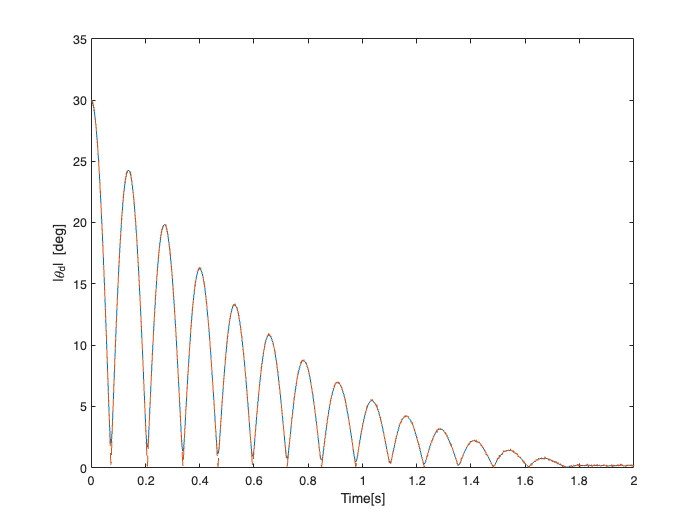

figure
plot(estimation.BB.thd_est.time, regression.smooth_signal)
hold on
plot(estimation.BB.thd_est.time, abs(estimation.BB.thd_est.signals.values),'--')

xlabel('Time[s]')
ylabel('|\theta_d| [deg]')
xlim([0 2])

Define vectors for regression. Firts consider the number of measures we want to consider.

regression.nmeas = 8;
regression.y = zeros(regression.nmeas,1);
regression.phi = zeros(regression.nmeas,2);

We have to select the first N peaks of interest. To select them in an accurate way we use a smothing of the funciotn to remove noise. Pay attention that when the size of the gaussina window is too large, we lose the fisrt peak. For this reason we calculate it in a second moment and we add it to the list. We observe from the figure below that we can consider at **maximum 12 peaks** (peaks form the 12 onward are not relevant).

Calculation of **N-1** peaks (apart from the first one)

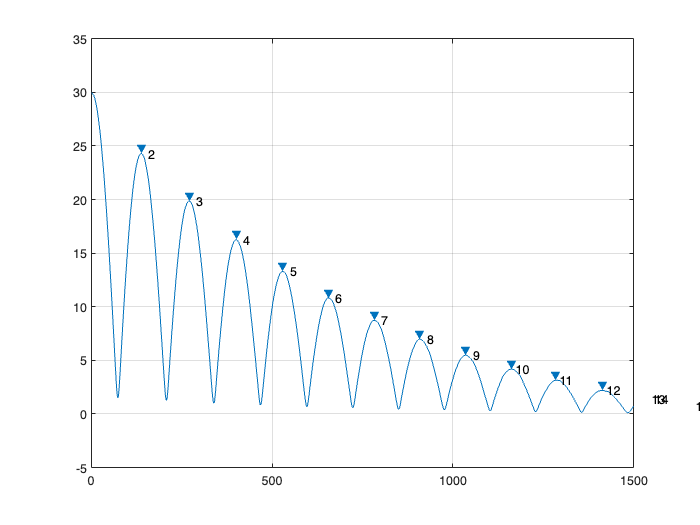

%[pks,locs] = findpeaks(regression.smooth_signal,'MinPeakDistance',0.1);
[pks,locs] = findpeaks(smoothdata(abs(estimation.BB.thd_est.signals.values),'gaussian',15));
figure
findpeaks(smoothdata(abs(estimation.BB.thd_est.signals.values),'gaussian',15))
text(locs+.02,pks,num2str((2:numel(pks)+1)'))
xlim([0 1500])

Calculation of the first peak. We observe that if the gaussian window is too small the machine detect close peaks thta are not relevant.

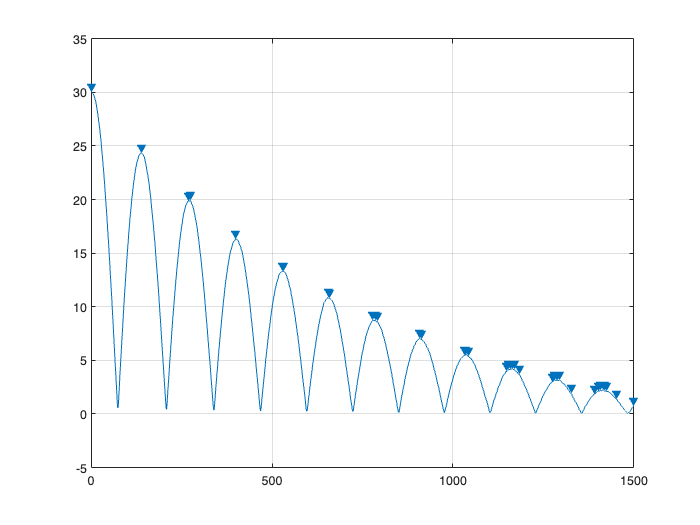

[pks1,locs1] = findpeaks(smoothdata(abs(estimation.BB.thd_est.signals.values),'gaussian',5),'MinPeakDistance',1);
figure
findpeaks(smoothdata(abs(estimation.BB.thd_est.signals.values),'gaussian',5),'MinPeakDistance',1)
xlim([0 1500])

Now insert correct data inside the vecotr used for regression. To compute regression.y we do not use the smoothed curves becuase they underestimate the real value we are looking for. We just compute a mean fo the values

regression.locs = zeros(regression.nmeas,1);
regression.locs(1) = locs1(1);
regression.locs(2:regression.nmeas) = locs(1:regression.nmeas-1);
disp(regression.locs'/1000)

    0.0020    0.1380    0.2710    0.4010    0.5300    0.6550    0.7820    0.9080



%regression.y(2:regression.nmeas) = pks(2:regression.nmeas);
%regression.y(1) = pks1(1);
regression.y(1) =  mean(abs(estimation.BB.thd_est.signals.values(regression.locs(1)-1:regression.locs(1)+1)));
i = 2;
while(i<= regression.nmeas)
    regression.y(i) =  mean(abs(estimation.BB.thd_est.signals.values(regression.locs(i)-2:regression.locs(i)+2)));
    i = i+1;
end

disp(regression.y')

   29.9859   24.3338   19.8810   16.3027   13.3066   10.8407    8.7079    7.0389



regression.y = log(regression.y);
i = 1;
while(i<= regression.nmeas)
    regression.phi(i,:) = [-i, 1];
    i = i+1;
end

Compute the estimate of the first parameter using **least squares.**

regression.theta = lsqr(regression.phi,regression.y);

lsqr converged at iteration 2 to a solution with relative residual 0.0025.


disp(regression.theta)

    0.2060
    3.6097



regression.d = regression.theta(1)/sqrt(regression.theta(1)^2 + pi^2);
disp(regression.d)

    0.0654



Estimate the time that intercurs between two consecutive peaks, the evaluate each frequency. **Pay attention**: we consider only nmeas-1 intervals, othwerrse we have close peaks thta alterates the final mean.

At the end we get the estimate of the **natural frequency**

regression.T = zeros(regression.nmeas-1,1);
regression.T(1) = locs(1) - locs1(1);
for i = 2:regression.nmeas-1
    regression.T(i) = locs(i) - locs(i-1);
end
% Conversion from ms to s
regression.T = regression.T/1000;
regression.w_temp = pi./regression.T;
regression.omega = mean(regression.w_temp);
disp(regression.omega)

   24.2919



regression.wn = regression.omega/sqrt(1-regression.d^2);
disp(regression.wn)

   24.3441



Final estimat of the required paramters.

In the fisrt formula check if there's a 2 or not

estimated.Bb = beam.Jb*2*regression.d*regression.wn;
estimated.k = beam.Jb*regression.wn^2;
disp(estimated.Bb)

    0.0045



disp(estimated.k)

    0.8297



Fiugure to check that the oscillation is correct

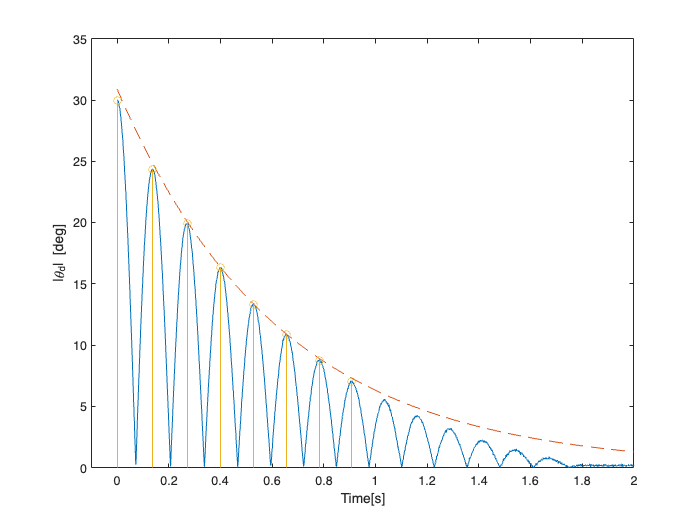

regression.time = 0:Ts:2;
regression.curve = regression.theta_deflection*1.03 * exp(-regression.d*regression.omega*regression.time);
%regression.curve = 30 * exp(-0.077*24.6*regression.time);

figure
plot(estimation.BB.thd_est.time, abs(estimation.BB.thd_est.signals.values))
hold on
plot(regression.time, regression.curve,'--', LineWidth=0.1)
stem(regression.locs/1000,exp(regression.y))
% xline(locs1(1)/1000,'--')
% for i = 1:regression.nmeas-1
%     xline(locs(i)/1000,'--')
% end
xlabel('Time[s]')
ylabel('|\theta_d| [deg]')
xlim([-0.1 2])